# Simulation of QPSK Direct Sequence Spread Spectrum Communication System

`Final Project of Digital Communication Systems Course. by Dr. Ahmadian`

`Name: Farzad Mohammadi`

`Student Number: 9630143`

`July 2020`

In this project we are assuming that a ***signle user*** wants to transmit an arbitrary bit stream through an ***AWGN channel*** using ***QPSK modulation*** and ***CDMA technique*** as multiple access scheme.

Also at the receiver we have ***Coherent Correlation Detector***

At the end we have provided all functions code in appendix section.

clear;
clc;
close;

## 1. Transmitter Side

### 1-1. Input Data

for input data we have random bit stream

we are sending ***20 bits*** which is ***10 symbols*** in QPSK Modulation

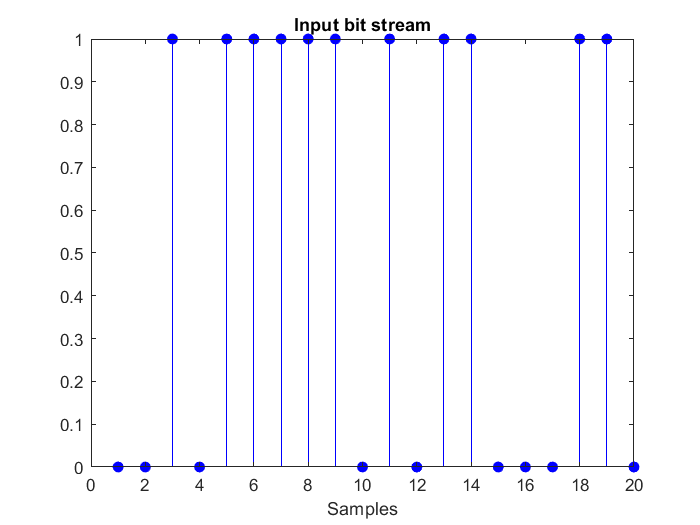

No_of_bits = 20;
data = randi([0 1], 1, No_of_bits);
stem(data, 'filled', 'blue')
title("Input bit stream")
xlabel("Samples")

because we want to use QPSK modulation our input bit stream length must be even

if rem(length(data), 2) == 1
    data = [data 0];
end

defining some characteristics of input signal like ***bit rate***, ***energy per bit*** and ***sample per pulse*** for simulation

***Note***: for ***sample_per_pulse*** variable higher values are better (it’s explained later in this file)

bit_rate = 1e3;
E_b = 10^-4;
sample_per_pulse = 20;

### 1-2. Line Coding

using polar_NRZ function we format our ***baseband signal*** with ***NRZ format***.

amplitude of baseband signal is based on bit rate and energy per bit

in figures below we can see our baseband signal in time and frequency domain

***NOTE:*** *polar_NRZ function** is provided in attached files*

[t, base_data, T_s, Amplitude] = polar_NRZ(data, bit_rate, E_b, sample_per_pulse);

creating frequency axis vector

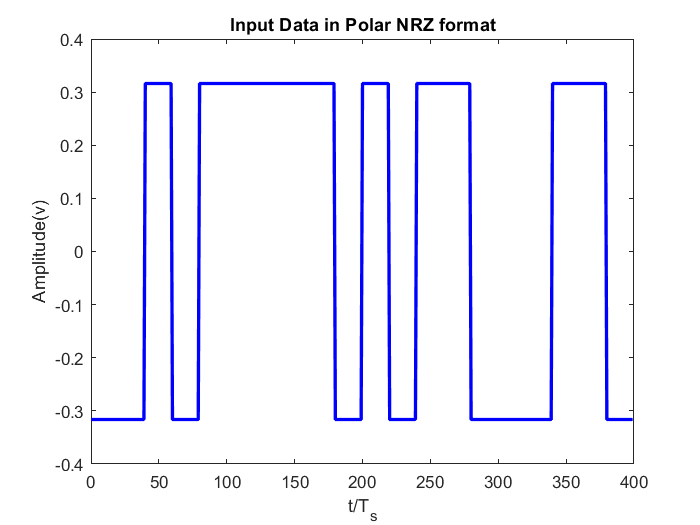

omega = 2 * pi * (0:length(t)-1) / length(t);
f = omega / (2 * pi * T_s);

plot(t/T_s, base_data, 'blue', 'linewidth', 2);
xlabel('t/T_s');
ylabel('Amplitude(v)');
title('Input Data in Polar NRZ format');

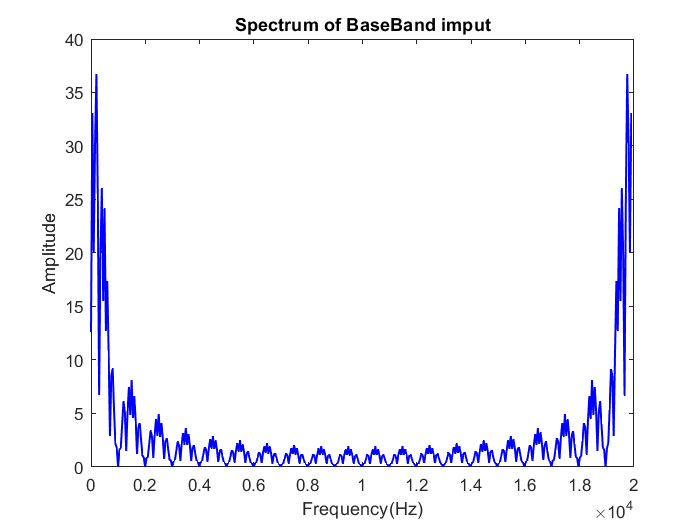

figure(31)
plot(f, abs(fft(base_data)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of BaseBand imput')

### 1-3. Serial to Parallel

Using Serial to parallel function we are calculating ***I-Channel*** and ***Q-Channel*** signals from input signal

***NOTE:*** *ser2par function* *is provided in attached files*

[I, Q, I_symbol, Q_symbol] = ser2par(base_data, sample_per_pulse);

Plotting I-Channel and Q-Channel signals in time and frequency domain

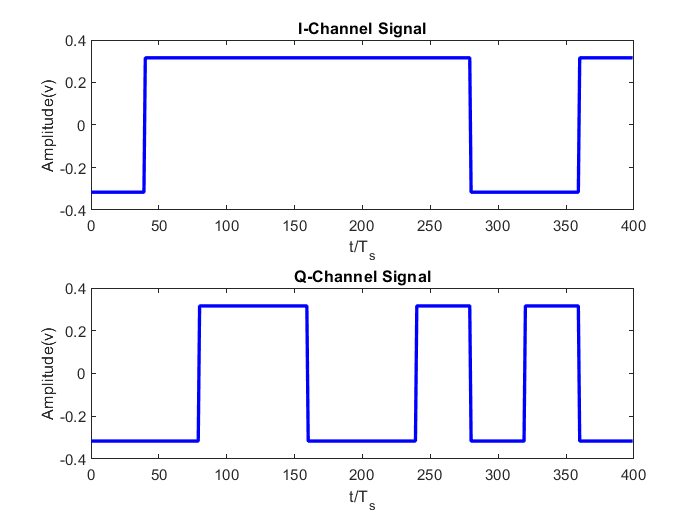

subplot(2,1,1);
plot(t/T_s, I, 'blue', 'LineWidth', 2);
xlabel('t/T_s');
ylabel('Amplitude(v)');
title('I-Channel Signal');

subplot(2,1,2);
plot(t/T_s, Q, 'blue', 'LineWidth', 2);
xlabel('t/T_s');
ylabel('Amplitude(v)');
title('Q-Channel Signal');

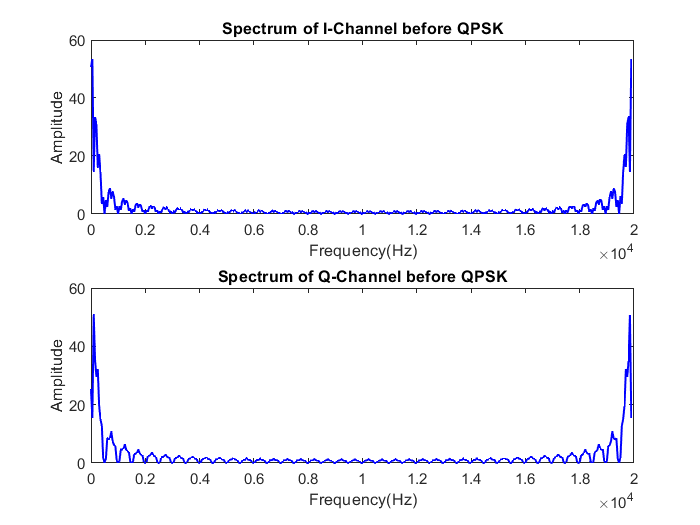

figure(32)
subplot(2,1,1)
plot(f, abs(fft(I)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of I-Channel before QPSK')
subplot(2,1,2)
plot(f, abs(fft(Q)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of Q-Channel before QPSK')

in figure below we can see our ***Constellation*** in Transmitter side

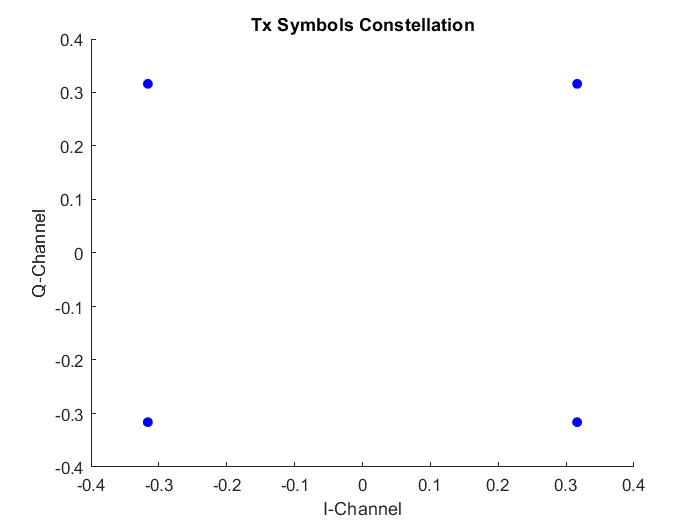

figure(40)
scatter(I_symbol, Q_symbol,'blue' ,'filled')
xlabel('I-Channel')
ylabel('Q-Channel')
title('Tx Symbols Constellation')

### 1-4. QPSK Modulation

In this section we are going to up-convert our baseband signal


$$\begin{array}{l}
I_m \left(t\right)=I\left(t\right)\ldotp \cos \left(2\;\ldotp \pi \;\ldotp f_c \;\ldotp t\right)\\
C_m \left(t\right)=C\left(t\right)\ldotp \sin \left(2\;\ldotp \pi \;\ldotp f_c \;\ldotp t\right)
\end{array}$$


here we are using $3\textrm{kHz}$ as central frequency

Note that because we are simulating continuous signal using discrete signals (there is no other way) our choice for ***central frequency*** is limited to our ***sampling frequency*** which is based on ***samples_per_pulse*** variable that we defined it at the beginning of the procedure.

f_c = 3e3;
I_m = I .* cos(2 * pi * f_c * t);
Q_m = Q .* -sin(2 * pi * f_c * t);

in figures below we can see our upconveted signals

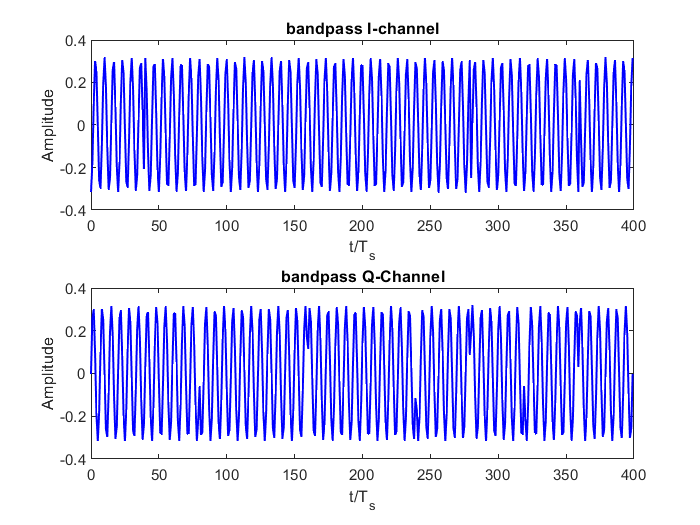

figure(3)
subplot(2,1,1)
plot(t/T_s, I_m, 'blue', 'linewidth', 1)
xlabel("t/T_s")
ylabel('Amplitude')
title('bandpass I-channel')
subplot(2,1,2)
plot(t/T_s, Q_m, 'blue', 'linewidth', 1)
xlabel("t/T_s")
ylabel('Amplitude')
title("bandpass Q-Channel")

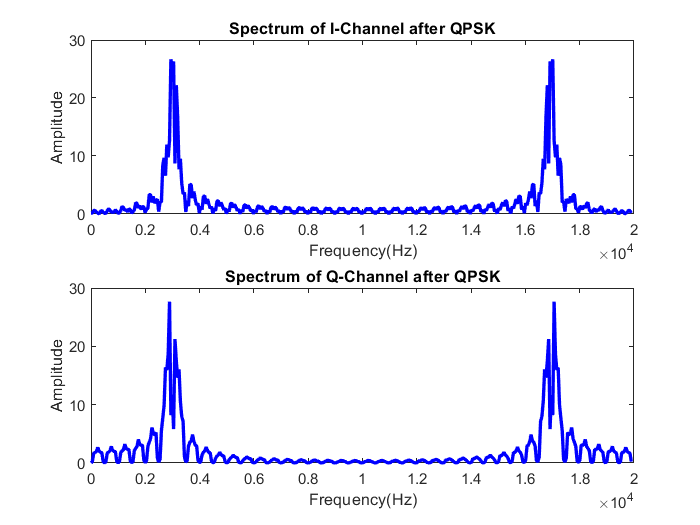

figure(33)
subplot(2,1,1)
plot(f, abs(fft(I_m)), 'blue', 'linewidth', 2)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of I-Channel after QPSK')
subplot(2,1,2)
plot(f, abs(fft(Q_m)), 'blue', 'linewidth', 2)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of Q-Channel after QPSK')

### 1-5. Spreading I-Channel and Q-Channel signals using PN Sequence

In this project we are using **pseudo**-**noise** sequence for spreading spectrum

our generator polynomial is: $\mathit{\mathbf{p}}={\mathit{\mathbf{x}}}^6 +{\mathit{\mathbf{x}}}^5 +{\mathit{\mathbf{x}}}^2 +\mathit{\mathbf{x}}+1$

here Processing Gain $\left(\textrm{PG}\right)\;$is 10.

***NOTE****: **pn_sequence function** is provided in attached files*

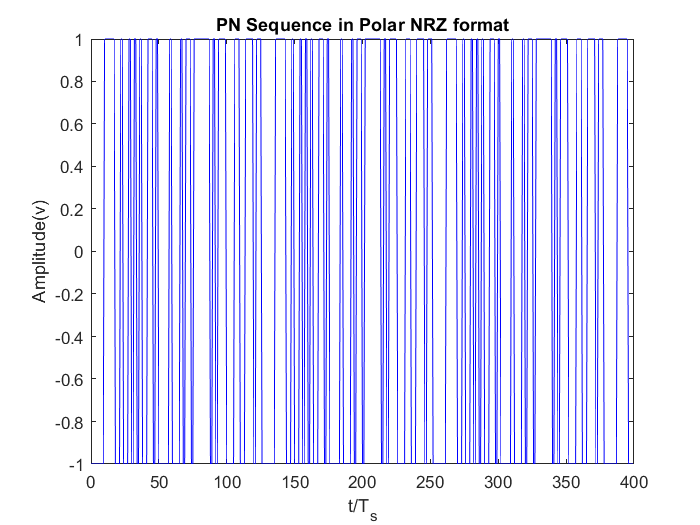

PG = 10;
polynomial = [1 1 0 0 1 1 1];
PN_sequence = pn_sequence(polynomial, PG, sample_per_pulse, length(data), bit_rate);
figure(4)
plot(t/T_s, PN_sequence, 'blue')
xlabel('t/T_s')
ylabel('Amplitude(v)')
title("PN Sequence in Polar NRZ format")


$$I_p \left(t\right)=I_m \left(t\right)\;\ldotp \textrm{pn}\left(t\right)$$



$$C_p \left(t\right)=C_m \left(t\right)\;\ldotp \textrm{pn}\left(t\right)$$


I_p = I_m .* PN_sequence;
Q_p = Q_m .* PN_sequence;


in figures below we can see our signal after spreading

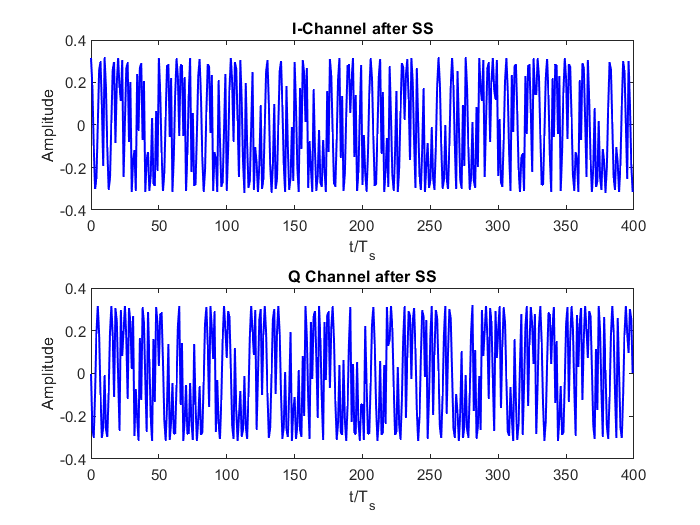

figure(4)
subplot(2,1,1)
plot(t/T_s, I_p, 'blue', 'linewidth', 1)
xlabel("t/T_s")
ylabel('Amplitude')
title('I-Channel after SS')
subplot(2,1,2)
plot(t/T_s, Q_p, 'blue', 'linewidth', 1)
xlabel("t/T_s")
ylabel('Amplitude')
title('Q Channel after SS')

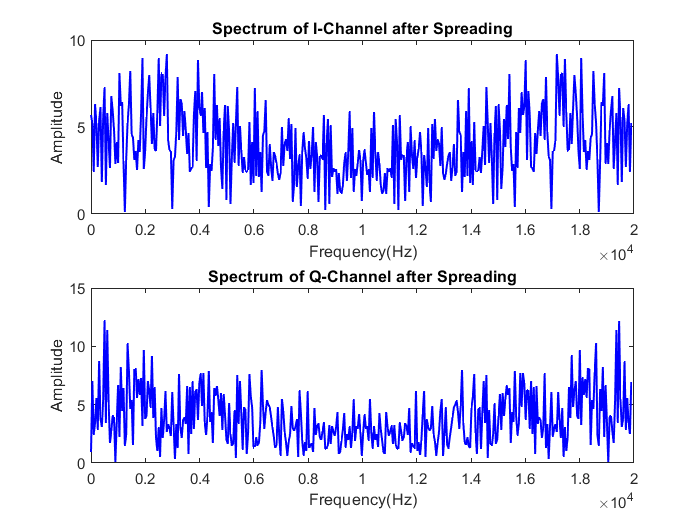

figure(34)
subplot(2,1,1)
plot(f, abs(fft(I_p)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of I-Channel after Spreading')
subplot(2,1,2)
plot(f, abs(fft(Q_p)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of Q-Channel after Spreading')

finally, transmitter output


$$S\left(t\right)=I_p \left(t\right)+C_p \left(t\right)$$


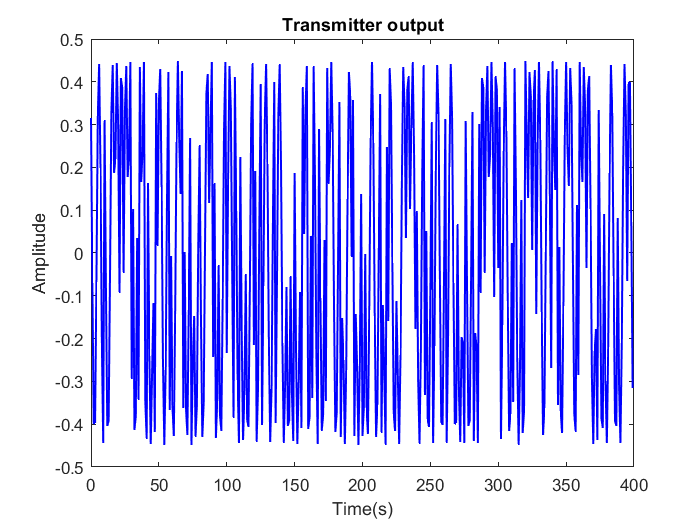

figure(5)
S = I_p + Q_p;
plot(t/T_s, S, 'blue', 'linewidth', 1)
xlabel("Time(s)")
ylabel('Amplitude')
title("Transmitter output")

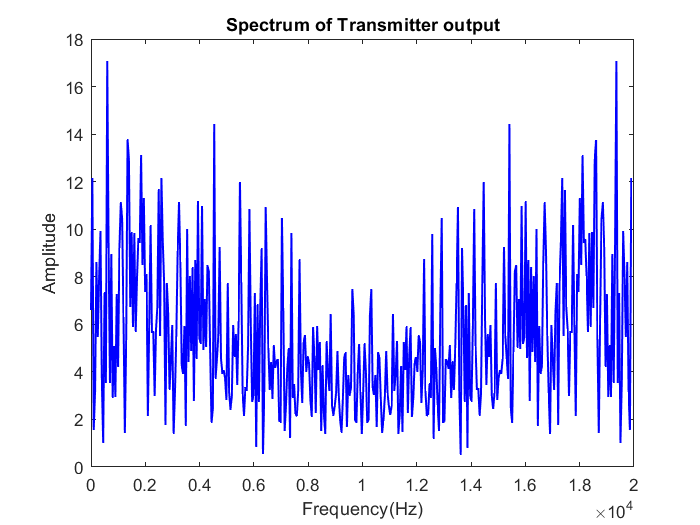

figure(35)
plot(f, abs(fft(S)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of Transmitter output')

## 2. Channel

### 2-1. Adding AWGN to signal in Channel

we are going to add ***AWGN*** to signal S such that at the Receiver input of we receive signal R with ***2 dB SNR***


$$R\left(t\right)=S\left(t\right)+\sigma_n \;n\left(t\right)$$



$$\begin{array}{l}
{\textrm{SNR}}_{\textrm{db}} =10\log_{10} \left(\frac{P_S }{\sigma_n^2 }\right)\\
P_S :\textrm{Power}\;\textrm{of}\;S\left(t\right)\\
\sigma_n :\textrm{Noise}\;\textrm{Power}\;\textrm{acording}\;\textrm{to}\;\textrm{desiered}\;\textrm{SNR}\\
n\left(t\right):\textrm{White}\;\textrm{Noise}\;\textrm{with}\;\textrm{zero}\;\textrm{mean}\;\textrm{and}\;\textrm{unity}\;\textrm{variance}
\end{array}$$


also for Signal Power from energy per bit relation we have:


$$E_b =\frac{P_S }{R_b }\Longrightarrow P_S =E_b \;\ldotp R_b$$


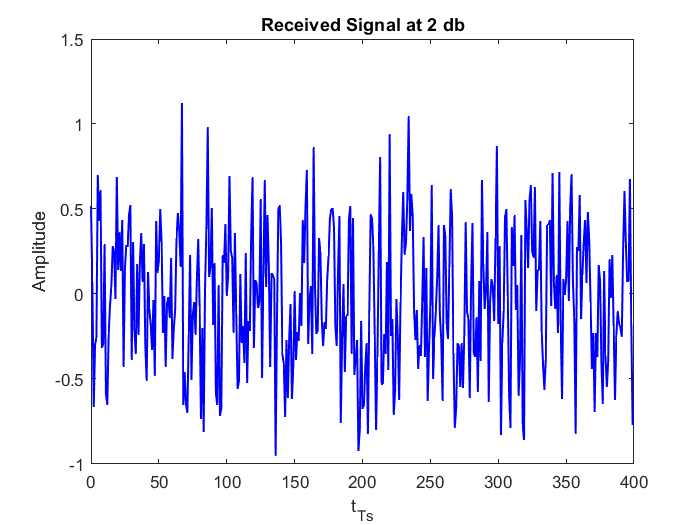

SNR = 2;
Signal_Power = E_b * bit_rate;
Noise_Power = Signal_Power / (10^(SNR/10));
noise = sqrt(Noise_Power) * randn(1 , length(t));

R = S + noise;
figure(6)
plot(t/T_s, R, 'blue', 'linewidth', 1)
title(['Received Signal' ' at ' num2str(SNR) ' db'])
xlabel("t_T_s")
ylabel('Amplitude')

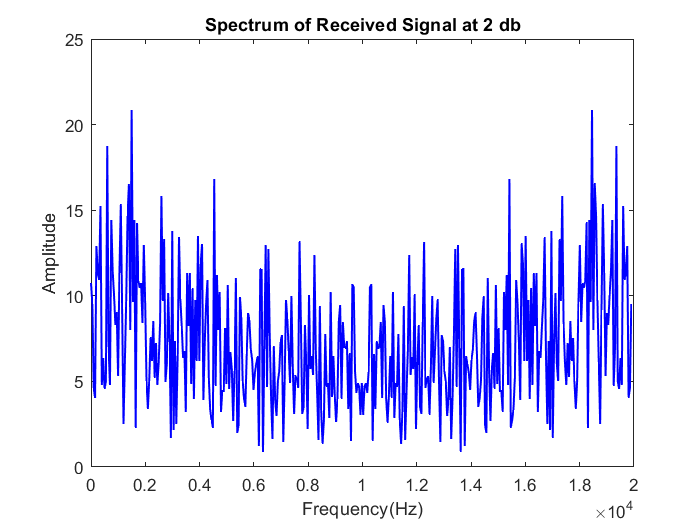

figure(36)
plot(f, abs(fft(R)) , 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title(['Spectrum of ' 'Received Signal' ' at ' num2str(SNR) ' db'])

## 3. Receiver Side

### 3-1. Dispreading Received Signal

At the receiver we have $R\left(t\right)$as our I and Q Channel signals

First, we are going to despread I and Q channels by multiplying these signals to the PN sequence which is the same as the sequence that we used in Transmitter.

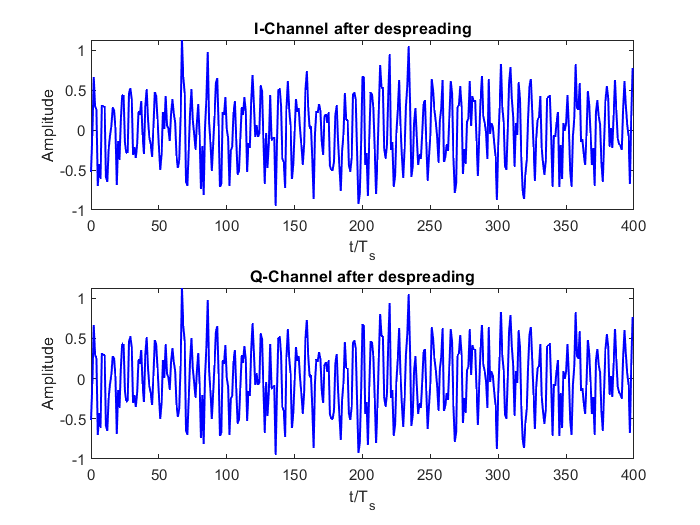

Ir = R .* PN_sequence;
Qr = R .* PN_sequence;

figure(7)
subplot(2,1,1)
plot(t/T_s,Ir, 'blue', 'linewidth', 1)
xlabel('t/T_s')
ylabel('Amplitude')
title('I-Channel after despreading')
subplot(2,1,2)
plot(t/T_s,Qr, 'blue', 'linewidth', 1)
xlabel('t/T_s')
ylabel('Amplitude')
title('Q-Channel after despreading')

Plotting Spectrum of I and Q channel after despreading

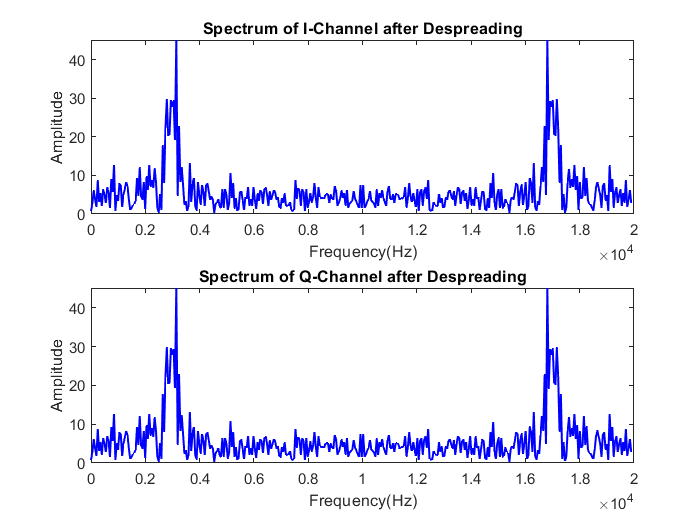

figure(8)
subplot(2,1,1)
plot(f, abs(fft(Ir)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of I-Channel after Despreading')
subplot(2,1,2)
plot(f,abs(fft(Qr)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of Q-Channel after Despreading')

### 3-2. QPSK Demodulation

In this section we are going to downconvert our passband signal

here we are using ***coherent*** modulation so we know our carriers.

also we need a ***lowpass filter*** for demodulation.

***low pass filter specification:***

- *pass band frequency*: $f_s =2\;R_b$

- *pass band ripple*: $R_P =0\;\textrm{db}$

- *stop band frequency*: $f_p =2\;R_b$

***NOTE:*** lowpass filter function script is provided in attached files

h = lowpass_filter(f, bit_rate * 2 , T_s);

Ir_m = 2 * Ir .* cos(2 * pi * f_c * t);
Qr_m = 2 * Qr .* -sin(2 * pi * f_c * t);

passing from **lowpass fiter**

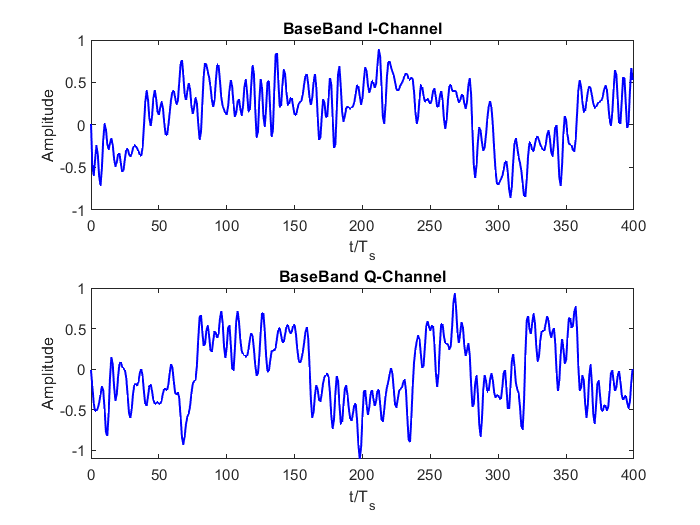

Ir_m = real(ifft( fft(Ir_m) .* h));
Qr_m = real(ifft( fft(Qr_m) .* h));


figure(9)
subplot(2,1,1)
plot(t/T_s,Ir_m, 'blue', 'linewidth', 1)
xlabel('t/T_s')
ylabel('Amplitude')
title('BaseBand I-Channel')
subplot(2,1,2)
plot(t/T_s,Qr_m, 'blue', 'linewidth', 1)
xlabel('t/T_s')
ylabel('Amplitude')
title('BaseBand Q-Channel')

plotting Spectrum of I and Q channel after demodulation

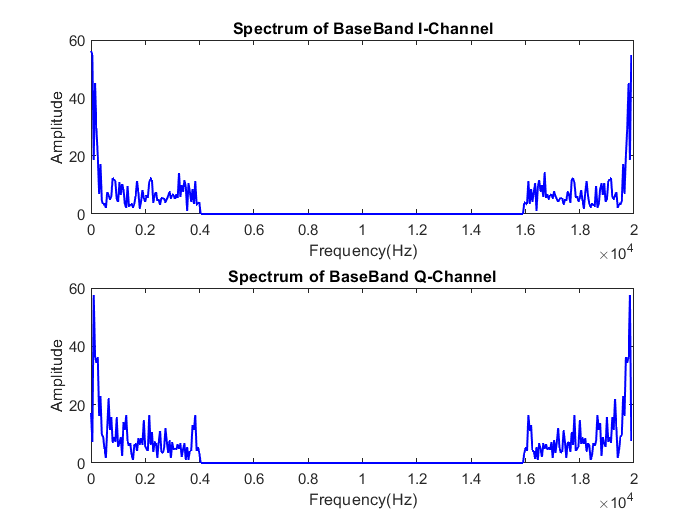

figure(10)
subplot(2,1,1)
plot(f, abs(fft(Ir_m)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of BaseBand I-Channel')
subplot(2,1,2)
plot(f,abs(fft(Qr_m)), 'blue', 'linewidth', 1)
xlabel('Frequency(Hz)')
ylabel('Amplitude')
title('Spectrum of BaseBand Q-Channel')

### 3-3. Correlation Detector and Parallel to Serial

In this project we have combined ***Correlation Detector*** and ***parallel to serial***

***NOTE:*** Correlation Detector script is provided in attached files

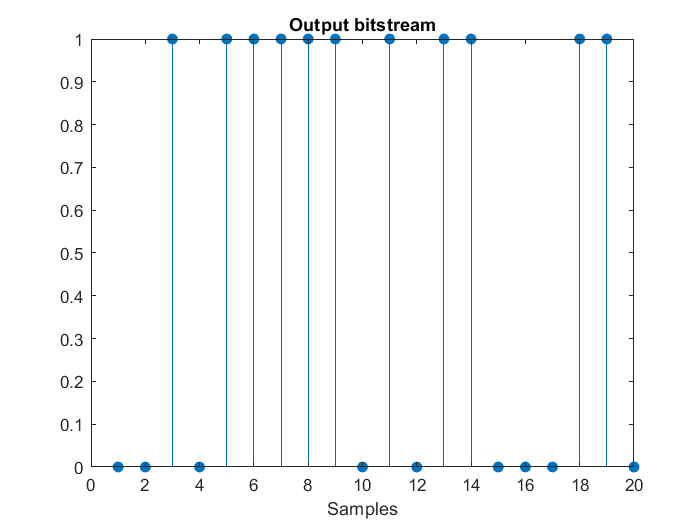

[output, I_Rx, Q_Rx] = par2ser(Ir_m, Qr_m, sample_per_pulse, Amplitude);
figure(11)
stem(output, 'filled')
xlabel('Samples')
title('Output bitstream')

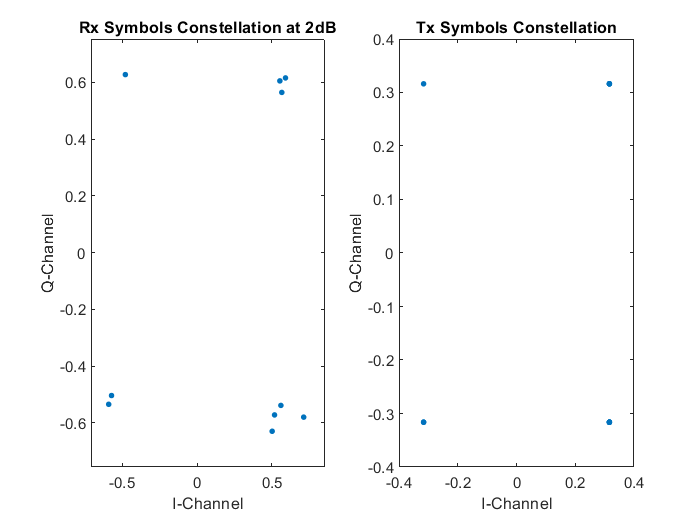


figure(41)
subplot(1,2,1)
plot(I_Rx ,Q_Rx, '.', 'MarkerSize',10)
axis([min(I_Rx)*1.2 max(I_Rx)*1.2 min(Q_Rx)*1.2 max(Q_Rx)*1.2])
xlabel('I-Channel')
ylabel('Q-Channel')
title(['Rx Symbols Constellation at ' num2str(SNR) 'dB'])

subplot(1,2,2)
plot(I_symbol , Q_symbol, '.', 'MarkerSize',10)
xlabel('I-Channel')
ylabel('Q-Channel')
title('Tx Symbols Constellation')

### 3-4. Results

No_of_error_bits = sum(output ~= data);
BER = No_of_error_bits / No_of_bits;
table(No_of_bits, bit_rate, E_b, SNR, ...
    PG, No_of_error_bits, BER)

ans = 1×7 table
    No_of_bits    bit_rate     E_b      SNR    PG    No_of_error_bits    BER
    __________    ________    ______    ___    __    ________________    ___

        20          1000      0.0001     2     10           0             0 


## Appendix

### i. Polar NRZ Line Coding Function

This function converts a bit stream as input with specific bit rate and energy to Polar NRZ format

`Parameters`:

- ***bit_stream***: input bit stream

- ***bit_rate***: input stream bit rate $\left(R_b \right)$

- ***E_b***: input stream bit energy $\left(E_b \right)$

- ***sample_per_pulse***: number of samples at output for each pulse

`Outputs`:

- ***t***: time axis vector

- ***X***: amplitude vector

- ***T_s***: sampling period

- ***A***: absolute amplitude of baseband signal

function [t, X, T_s, A] = polar_NRZ(bit_stream, bit_rate, E_b, sample_per_pulse)

Calculating total output signal duration in seconds

T = length(bit_stream) / bit_rate;

Number of total samples at output

N = sample_per_pulse * length(bit_stream);

Calculating magnitude amplitude of each pulse at output


$$E=A^2 T_b =\frac{A^2 }{R_b }\;\Longrightarrow \;A=\sqrt{{E\;R}_b }$$


A = sqrt(E_b * bit_rate);

t = linspace(0,T,N);
T_s = t(2) - t(1);
X(N) = 0;

Calculating output signal

for i = 0:length(bit_stream) - 1
    if bit_stream(i + 1) == 1
        X(i * sample_per_pulse + 1 :  ( i+1 )*sample_per_pulse ) = A;
    else
       X(i * sample_per_pulse + 1 :  ( i+1 )*sample_per_pulse ) = -A; 
    end
end
end

### ii. Serial To Parallel Function

This function converts a serial signal with bit rate of R to two parallel signal with bit rate of $\frac{R_b }{2}$

`Parameters`:

- ***input***: input bit stream

- ***sample_per_pulse***: number of samples at output for each pulse

`Output`:

- ***I: ***I-Channel signal

- ***Q: ***Q-Channel signal

- ***I_symbol: ***I-channel symbol vector

- ***Q_symbol: ***Q-Channel symbol vector

function [I, Q, I_symbol, Q_symbol] = ser2par(input , sample_per_pulse)
n = 2 * sample_per_pulse;
I(length(input)) = 0;
Q(length(input)) = 0;
I_symbol(length(input)/(2*sample_per_pulse)) = 0;
Q_symbol(length(input)/(2*sample_per_pulse)) = 0;
k = 0;
X1_k = 0;
X2_k = 0;
for i = 1 : sample_per_pulse : length(input)
    if rem(k,2) == 0
        
        I(X1_k*n + 1 : (X1_k+1)*n) = pulse_generator(sign(input(i)), abs(input(i)), sample_per_pulse);
        I_symbol(X1_k+1) = input(i);
        X1_k = X1_k + 1;
    else
        amplitude = pulse_generator(sign(input(i)), abs(input(i)), sample_per_pulse);
        Q(X2_k*n + 1 : (X2_k+1)*n) = amplitude;
        Q_symbol(X2_k+1) = input(i);
        X2_k = X2_k + 1;
    end
    k = k + 1;
end

    function [x] = pulse_generator(sign, amplitude, sample_per_pulse)
        x(2 * sample_per_pulse) = 0;
        if sign > 0
            x = amplitude;
        else
            x = -amplitude;
        end
    end
end

### iii. PN Sequence Generator Function

This method calculates PN sequence  with Fibonacci format

`Parameters`:

- ***polynomial***: PN sequence generator polynomial in matrix form

- ***PG***: ratio of spreaded signal bandwidth to original signal bandwidth (Processing Gain)

- ***symbol_per_pulse***: number of samples per one pulse at output

- ***data_bit_count***: length of input data bit stream that

- ***data_bit_rate***: input data bit rate

***NOTE 1***: $\textrm{PG}=\frac{T_b }{T_c }$,    where $T_b$ is bit rate of base band input data bit stream and $T_c$ is chip rate of PN sequence

***NOTE 2***: $\textrm{PG}$ must be an integer and $\textrm{PG}\ge 1\ldotp$ also symbol per pulse number must be dividable by PG

function [x] = pn_sequence(polynomial, PG, symbol_per_pulse, data_bit_count, data_bit_rate)
if PG < 1 || rem(PG,1) ~= 0 || rem(symbol_per_pulse, PG) ~= 0
    error("PG must be an integer and greater than 1 ( or equal ) and\n" + ...
        " symbol per pulse number must be dividable by PG");
end
n = symbol_per_pulse / PG;
chip_rate = data_bit_rate / PG;

order = length(polynomial) - 1;
mask(order) = 1;
init(order) = 0;
init(1) = 1;
Seqcount = PG * data_bit_count;

pnSequence = comm.PNSequence('Polynomial',polynomial,'InitialConditions', init,...
'SamplesPerFrame',Seqcount, 'Mask', mask);
pn = pnSequence();
bit_stream = pn(1:Seqcount);

[~, x] = polar_NRZ(bit_stream, chip_rate, (1 / (chip_rate)), n);
end

### iv. LowPass Filter Function

This function implements a low pass filter

***low pass filter specification:***

- *pass band frequency*: $f_s =2\;R_b$

- *pass band ripple*: $R_P =0\;\textrm{db}$

- *stop band frequency*: $f_p =2\;R_b$

`Parameters:`

- ***f***: frequency vector

- ***R_b***: bit rate of signal

- ***T_s***: sampling period

`Output:`

- ***h***: frequency responce of the filter

function [h] = lowpass_filter(f, R_b, T_s)


h(length(f)) = 0;
low_index = find(f < 2*R_b);
high_index = find(f > ((1/T_s) - 2*R_b));
index = [low_index high_index];
h(index) = 1;
end

### v. Correlation Detector and Parallel to Serial Function

This function first find the correlation of I and Q channel signals, then it compares this correlation value with signals space and selects one with minimum difference

`Parameters`:

- ***I***: I-Channel signal

- ***Q***: Q-Channel signal

- ***sample_per_pulse***: number of samples per one pulse at output

- ***Amplitude***: amplitude of baseband signal

`outputs`:

- ***bit_stream***: output bit stream

- ***Rx_I_symbols: ***I-Channel symbol vector

- ***Rx_Q_symbols: ***Q-Channel symbol vector

function [bit_stream, Rx_I_symbols, Rx_Q_symbols] = par2ser(I, Q, sample_per_pulse, Amplitude)
len = length(I)/(sample_per_pulse);
bit_stream(len) = 0;
Rx_I_symbols(len/2) = 0;
Rx_Q_symbols(len/2) = 0;
k = 1;

for i = 1 : len/2

calculating correlation in I-channel

    cor = sum(I(1 + 2*(i-1)*sample_per_pulse : 2*i*sample_per_pulse)) / (2*sample_per_pulse);
    if cor > 0
        Rx_I_symbols(i) = sqrt(cor);
    else
        Rx_I_symbols(i) = -imag(sqrt(cor));
    end
    

    comparing correlation value with signal space 

    if abs(cor - Amplitude)^2 < abs(cor + Amplitude)^2
        bit_stream(k) = 1;
    end
    
    k = k + 1;

calculating correlation in Q-channel

    cor = sum(Q(1 + 2*(i-1)*sample_per_pulse : 2*i*sample_per_pulse)) / (2*sample_per_pulse);
    if cor > 0
        Rx_Q_symbols(i) = sqrt(cor);
    else
        Rx_Q_symbols(i) = -imag(sqrt(cor));
    end

comparing correlation value with signal space 

    if abs(cor - Amplitude)^2 < abs(cor + Amplitude)^2
        bit_stream(k) = 1;
    end
    k = k + 1;
end
end